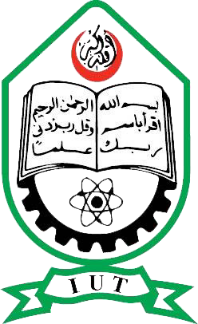

Islamic University of Technology

Name                          : Ahnaf Sakif

Student ID                   : 220021127 

Section                        : A-(01) 

Department                 :EEE 

# Lab 10 Assignment Test Cases

%Problem 1
jump_search([1, 3, 5, 7, 9, 11, 13, 15, 17, 19], 7)

ans = logical
   1


jump_search([2, 4, 6, 8, 10, 12, 14, 16, 18, 20], 15)

ans = logical
   0


%Problem 2
manual_sort([64, 34, 25, 12, 22, 11, 90])

ans =     11    12    22    25    34    64    90


manual_sort([5, 2, 8, 1, 9])

ans =      1     2     5     8     9


%Problem 3
job_seq([4, 1, 1, 1], [20, 10, 40, 30])

ans = 'ca'

job_seq([2, 1, 2, 1, 3], [100, 19, 27, 25, 15])

ans = 'ace'

job_seq([5, 3, 3, 2, 4, 2], [200, 180, 190, 300, 120, 100])

ans = 'dacbe'

%Problem 4
balance('(()()())')

ans = logical
   1


balance('(()()())(')

ans = logical
   0


balance('(())))()())')

ans = 0

balance('(((()))((())))') 

ans = logical
   1


balance('(()()()()((()))()()()(((()))))') 

ans = logical
   1


balance('(()()(((((((((((()))))') 

ans = logical
   0


%Problem 5
jump_search_leaps([1,5,9,14,17,18,23,33,36,38], 38, 2)

ans = 5

jump_search_leaps([5, 10, 10, 10, 25, 30, 35, 35, 55, 65, 100, 600, 4000, 10000, 10000, 30000, 30000, 48000], 30, 2)

ans = 3

jump_search_leaps([2,5,6,9,12,14,15,16,17,19,31], 2, 5)

ans = -1

jump_search_leaps([5, 10, 10, 10, 25, 30, 35, 35, 55, 65, 100, 600, 4000, 10000, 10000, 30000, 30000, 48000], 10000, 4)

ans = 4

%Problem 6
remove_trailing_zeros([1 2 0; 0 3 0; 0 0 0])

ans =      1     2
     0     3


remove_trailing_zeros([1 2 0 4 0; 2 3 0 5 0; 3 4 0 6 0; 1 0 0 0 0])

ans =      1     2     0     4
     2     3     0     5
     3     4     0     6
     1     0     0     0


remove_trailing_zeros([1 1 0 0 0; 1 0 0 0 0; 0 0 0 3 0; 0 0 0 0 0; 0 0 0 0 0])

ans =      1     1     0     0
     1     0     0     0
     0     0     0     3


%Problem 7
rod_cutting([1,5,8,9,10,17,17,20], 8)

ans = 22

rod_cutting([1,5,8,9,10,17,17,20], 7)

ans = 18

rod_cutting([10,5,3,18], 2)

ans = 20

rod_cutting([10,5,36,18,36], 5)

ans = 56

%Problem 8
tortoise_hare(6)

ans = logical
   1


tortoise_hare(10)

ans = logical
   1


tortoise_hare(0)

ans = logical
   1


tortoise_hare(-6)

ans = logical
   1


tortoise_hare(15)

ans = logical
   1


%Problem 9
dont_be_greedy([100, 80, 60], [2, 1, 3])

ans =      1     2     3


dont_be_greedy([90, 70, 50, 80], [2, 1, 2, 1])

ans =      1     4


%Problem 10
euler_11()

ans = 70600674

# Functions:

# Problem 1

function [found, index] = jump_search(arr, val)
n = length(arr);
step = floor(sqrt(n));
prev = 1;
while arr(min(step, n)) < val
    prev = step;
    step = step + floor(sqrt(n));
    if prev >= n
        found = false;
        index = -1;
        return;
    end
end
while arr(prev) < val
    prev = prev + 1;
    if prev == min(step, n)
        found = false;
        index = -1;
        return;
    end
end
if arr(prev) == val
    found = true;
    index = prev;
else
    found = false;
    index = -1;
end
end

# Problem 2

function sorted_array = manual_sort(arr)
n = length(arr);
sorted_array = arr;
for i = 1:n-1
    min_idx = i;
    for j = i+1:n
        if sorted_array(j) < sorted_array(min_idx)
            min_idx = j;
        end
    end
    temp = sorted_array(min_idx);
    sorted_array(min_idx) = sorted_array(i);
    sorted_array(i) = temp;
end
end

# Problem 3

function [jobs, profit] = job_seq(deadlines, profits)
alphabets='abcdefghijkl';
n = length(deadlines);
max_deadline = max(deadlines);
job_indices = 1:n;
[sorted_profits, sort_idx] = sort(profits, 'descend');
sorted_deadlines = deadlines(sort_idx);
sorted_jobs = job_indices(sort_idx);
result = zeros(1, max_deadline);
selected_jobs = [];
total_profit = 0;
for i = 1:n
    for j = min(sorted_deadlines(i), max_deadline):-1:1
        if result(j) == 0
            result(j) = sorted_jobs(i);
            selected_jobs = [selected_jobs, sorted_jobs(i)];
            total_profit = total_profit + sorted_profits(i);
            break;
        end
    end
end
jobs = alphabets(selected_jobs);
profit = total_profit;
end

# Problem 4

function result = balance(expr)
count = 0;
for i = 1:length(expr)
    if expr(i) == '('
        count = count + 1;
    elseif expr(i) == ')'
        count = count - 1;
        if count < 0
            result = 0;
            return;
        end
    end
end
result = (count == 0);
end

# Problem 5

function leaps = jump_search_leaps(arr, x, n)
    L = numel(arr);
    leaps = 0;
    pos = 1;
    while pos + n <= L && arr(pos + n) < x
        pos = pos + n;
        leaps = leaps + 1;
    end
    startIdx = pos + 1;
    endIdx   = min(pos + n, L);
    found = false;
    for k = startIdx:endIdx
        leaps = leaps + 1;
        if arr(k) == x
            pos = k;
            found = true;
            break;
        end
    end
    if ~found
        leaps = -1;
        return;
    end
    while pos > 1 && arr(pos-1) == x
        pos = pos - 1;
        leaps = leaps + 1;
    end
end

# Problem 6

function result = remove_trailing_zeros(matrix)
[rows, cols] = size(matrix);
last_row = rows;
last_col = cols;
for i = rows:-1:1
    if any(matrix(i, :) ~= 0)
        last_row = i;
        break;
    end
    last_row = i - 1;
end
if last_row == 0
    result = [];
    return;
end
for j = cols:-1:1
    if any(matrix(1:last_row, j) ~= 0)
        last_col = j;
        break;
    end
    last_col = j - 1;
end
if last_col == 0
    result = [];
    return;
end
result = matrix(1:last_row, 1:last_col);
end

# Problem 7

function max_revenue = rod_cutting(prices, L)
    dp = zeros(1, L+1);
    nPrices = numel(prices);
    for i = 1:L
        for j = 1:i
            if j <= nPrices
                dp(i+1) = max(dp(i+1), dp(i-j+1) + prices(j));
            end
        end
    end
    max_revenue = dp(L+1);
end

# Problem 8

function result = tortoise_hare(x)
if x == 0
    result = true;
    return;
end
if x < 0
    result = tortoise_hare(-x);
    return;
end
n = 1;
sum_pos = 0;
while sum_pos < x
    sum_pos = sum_pos + n;
    n = n + 1;
end
if sum_pos == x
    result = true;
    return;
end
diff = sum_pos - x;
if mod(diff, 2) == 0
    result = true;
else
    result = false;
end
end

# Problem 9

function order = dont_be_greedy(marks, deadlines)
n = length(marks);
jobs = 1:n;
[sorted_marks, idx] = sort(marks, 'descend');
sorted_deadlines = deadlines(idx);
sorted_jobs = jobs(idx);
max_deadline = max(deadlines);
result = zeros(1, max_deadline);
order = [];
for i = 1:n
    for j = min(sorted_deadlines(i), max_deadline):-1:1
        if result(j) == 0
            result(j) = sorted_jobs(i);
            order = [order, sorted_jobs(i)];
            break;
        end
    end
end
end

# Problem 10

function max_product = euler_11()
grid = [
    08, 02, 22, 97, 38, 15, 00, 40, 00, 75, 04, 05, 07, 78, 52, 12, 50, 77, 91, 08;
    49, 49, 99, 40, 17, 81, 18, 57, 60, 87, 17, 40, 98, 43, 69, 48, 04, 56, 62, 00;
    81, 49, 31, 73, 55, 79, 14, 29, 93, 71, 40, 67, 53, 88, 30, 03, 49, 13, 36, 65;
    52, 70, 95, 23, 04, 60, 11, 42, 69, 24, 68, 56, 01, 32, 56, 71, 37, 02, 36, 91;
    22, 31, 16, 71, 51, 67, 63, 89, 41, 92, 36, 54, 22, 40, 40, 28, 66, 33, 13, 80;
    24, 47, 32, 60, 99, 03, 45, 02, 44, 75, 33, 53, 78, 36, 84, 20, 35, 17, 12, 50;
    32, 98, 81, 28, 64, 23, 67, 10, 26, 38, 40, 67, 59, 54, 70, 66, 18, 38, 64, 70;
    67, 26, 20, 68, 02, 62, 12, 20, 95, 63, 94, 39, 63, 08, 40, 91, 66, 49, 94, 21;
    24, 55, 58, 05, 66, 73, 99, 26, 97, 17, 78, 78, 96, 83, 14, 88, 34, 89, 63, 72;
    21, 36, 23, 09, 75, 00, 76, 44, 20, 45, 35, 14, 00, 61, 33, 97, 34, 31, 33, 95;
    78, 17, 53, 28, 22, 75, 31, 67, 15, 94, 03, 80, 04, 62, 16, 14, 09, 53, 56, 92;
    16, 39, 05, 42, 96, 35, 31, 47, 55, 58, 88, 24, 00, 17, 54, 24, 36, 29, 85, 57;
    86, 56, 00, 48, 35, 71, 89, 07, 05, 44, 44, 37, 44, 60, 21, 58, 51, 54, 17, 58;
    19, 80, 81, 68, 05, 94, 47, 69, 28, 73, 92, 13, 86, 52, 17, 77, 04, 89, 55, 40;
    04, 52, 08, 83, 97, 35, 99, 16, 07, 97, 57, 32, 16, 26, 26, 79, 33, 27, 98, 66;
    88, 36, 68, 87, 57, 62, 20, 72, 03, 46, 33, 67, 46, 55, 12, 32, 63, 93, 53, 69;
    04, 42, 16, 73, 38, 25, 39, 11, 24, 94, 72, 18, 08, 46, 29, 32, 40, 62, 76, 36;
    20, 69, 36, 41, 72, 30, 23, 88, 34, 62, 99, 69, 82, 67, 59, 85, 74, 04, 36, 16;
    20, 73, 35, 29, 78, 31, 90, 01, 74, 31, 49, 71, 48, 86, 81, 16, 23, 57, 05, 54;
    01, 70, 54, 71, 83, 51, 54, 69, 16, 92, 33, 48, 61, 43, 52, 01, 89, 19, 67, 48;
];
max_product = 0;
[rows, cols] = size(grid);
for i = 1:rows
    for j = 1:cols-3
        horizontal = grid(i,j) * grid(i,j+1) * grid(i,j+2) * grid(i,j+3);
        max_product = max(max_product, horizontal);
    end
end
for i = 1:rows-3
    for j = 1:cols
        vertical = grid(i,j) * grid(i+1,j) * grid(i+2,j) * grid(i+3,j);
        max_product = max(max_product, vertical);
    end
end
for i = 1:rows-3
    for j = 1:cols-3
        diagonal_down = grid(i,j) * grid(i+1,j+1) * grid(i+2,j+2) * grid(i+3,j+3);
        max_product = max(max_product, diagonal_down);
    end
end
for i = 1:rows-3
    for j = 4:cols
        diagonal_up = grid(i,j) * grid(i+1,j-1) * grid(i+2,j-2) * grid(i+3,j-3);
        max_product = max(max_product, diagonal_up);
    end
end
end